s=tf('s');

%Ki =-81; % 50
%Kp = 14 %-100;% 14
%Ki = Kp*50/14 % pour garder la meme phase
Ki = 1e2 %50 %1e0

Ki = 100

Kp = Ki* 1e2 %14 %Ki*1e2

Kp = 10000

K = Kp+Ki/s

K =
 
  10000 s + 100
  -------------
        s
 
Continuous-time transfer function.



disp(["1/Ki = " 1/Ki "Kp/Ki =" Kp/Ki])

    "1/Ki = "    "0.01"    "Kp/Ki ="    "100"




14+50/s

ans =
 
  14 s + 50
  ---------
      s
 
Continuous-time transfer function.




1/Ki

ans = 0.0100

1/50

ans = 0.0200


(1+Kp*s/Ki)/s-(1+14*s/50)/s

ans =
 
  498600 s^2
  ----------
   5000 s^2
 
Continuous-time transfer function.





G = 1/(s+1);

FTBO = K*G

FTBO =
 
  10000 s + 100
  -------------
     s^2 + s
 
Continuous-time transfer function.




FTBF_G = G/(1+G);

FTBF_mat = FTBO/(1+FTBO); % matlab

FTBF_calc = (Kp*s + Ki)/(s^2 + (Kp+1)*s + Ki); % calcul

FTBF_fix = (14*s + 50)/(s^2 + (14+1)*s + 50);

Etonnament on remarque que les FTBF obtenu par matlab et par calcul sot differentes

On va verifier la coherence des 2 fonctions de transfert et on prendr preferablement celle obtenu par calcul

%step(FTBF_mat,FTBF_calc)

%step(FTBF_calc)

On remarque que FTBF_calc $\sim$ FTBF_mat

FTBF = FTBF_calc;

figure
step(FTBF,'b',FTBF_fix,'r--', FTBF_G, 'g.-')
legend('FTBF','FTBF fix','FTBF G','Location','SouthEast')
figure
bode(K*G,'b-*',(14+50/s)*G,'r--', G, 'g.-', K)
legend('FTBO','FTBO fix','G','K','Location','NorthEast')
figure
bode(FTBF,'b',FTBF_fix,'r--', FTBF_G, 'g.-')
legend('FTBF','FTBF fix','FTBF G','Location','SouthEast')
figure
nyquist(K*G,'b',(14+50/s)*G,'r--', G, 'g.-')
legend('FTBO','FTBO fix','G','Location','SouthEast')
figure
rlocus(K*G,'b',(14+50/s)*G,'r--', G, 'g.-')
legend('FTBF','FTBF fix','FTBF G','Location','northwest')

%sisotool(G)

On a rajouter un Gain, un integrateur et un zero à G

en effet $K=0.02\frac{1+0.28s}{s}$

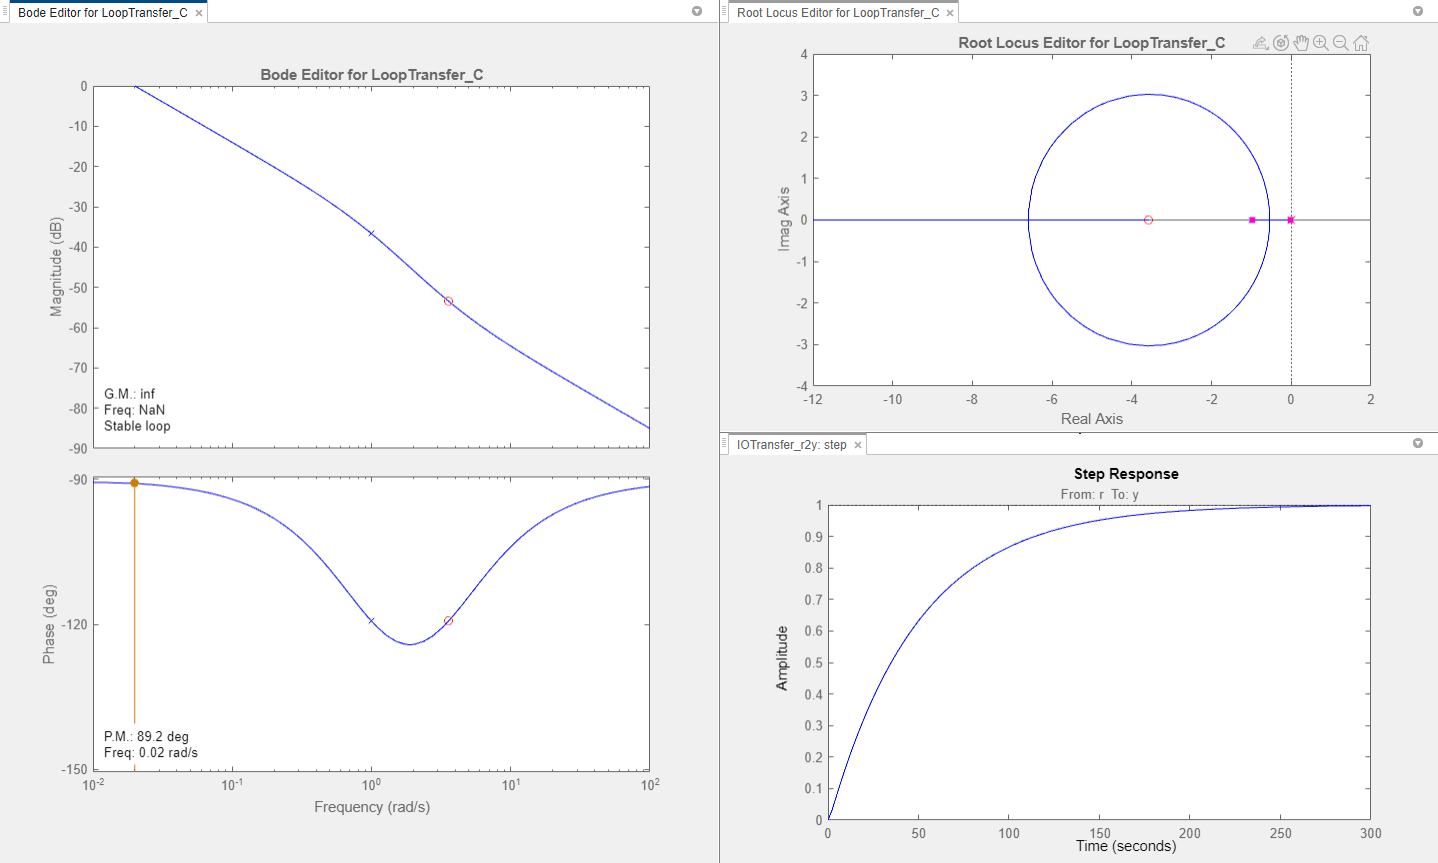

On obtient ceci sur sisotool: 

nyquist(FTBO,'r')
legend('FTBO', 'Location','SouthEast')

A = [0 1 0; 0 0 1; -50 -15 -1];
B = [ 0 0 1]';
C = [0 15 50];

[A_G, B_G, C_G, D_G] = tf2ss(cell2mat(FTBF.Numerator),cell2mat(FTBF.Denominator))

eig(A)
eig(A_G)
eig(FTBF)

G_5=(exp(-1.5*s))/((2*s+1)*(0.7*s+1)*(s^2+40*s+1600))
G_5_wo_r=1/((2*s+1)*(0.7*s+1)*(s^2+40*s+1600))

eig(G_5)

bode(G_5)

s=tf('s');

G_2=(5*s-4)/((s-1)*(s-0.5))
T_2= G_2/(1+G_2)

T_2 - (5*s-4)/((s+4.3117)*(s-0.8117))
step(T_2,(5*s-4)/((s^2+3.5*s-3.5)))

syms x
x=sym('x')
time_fct_2 = ilaplace((5*x-4)/((x+4.3117)*(x-0.8117)))
195/17078
85195/17078

syms t
t=sym('t')
time_fct_2_calc = 4.988*exp(-4.3117*t) + 0.00114*exp(0.8817*t)

fplot(time_fct_2 - time_fct_2_calc)

syms L T R C t  X(t) x1(t) x2(t) X_k(k) x1_k(k) x2_k(k) Vt(t) k V_k(k) A_3(R,L,C) B_3(L) 
syms dX(t,R,L,C) dx1(t) dx2(t) Ad_3(R,L,C,T) Bd_3(R,C,T) Ad_3_calc(R,L,C,T) Bd_3_calc(R,C,T) 
syms X_k_calc(k) x1_k_calc(k) x2_k_calc(k) X_k1(k,R,L,C,T) x1_k1(k) x2_k1(k) X_k_calc1(k,R,L,C,T) x1_k_calc1(k) x2_k_calc1(k)

A_3(R,L,C) = [0 -1/L; 1/C -1/R*C]
B_3(L) = [1/L; 0]
X(t)=[x1(t); x2(t)]
dX(t,R,L,C) = [dx1(t); dx2(t)]
dX(t,R,L,C) = A_3(R,L,C)*X(t)+B_3(L)*Vt(t)
%---
%sys_3 = ss(A_3,B_3,0,0)
%sys_3_d=c2d(sys_3,T)
%---
Ad_3(R,L,C,T) = [0 exp(-T/L); exp(T/C) exp(-T/R*C)]
Bd_3(R,C,T) = [(1/R - exp(T/C)); (-1/R *exp(T/C) - exp(-T/R*C))]
X_k(k) = [x1_k(k); x2_k(k)]
X_k1(k,R,L,C,T) = [x1_k1(k); x2_k1(k)]
X_k1(k,R,L,C,T) = Ad_3(R,L,C,T)*X_k(k)+Bd_3(R,C,T)*V_k(k)
%---
Ad_3_calc(R,L,C,T) = (1/(L*(T+R*C)+T^2*R)) * [T+R*C -R*C*T; T*R*L/(T+R*C) (R*C*(L*(T+R*C)+R*T^2)-T^2*R^2*C)/(T+R*C)]
Bd_3_calc(R,C,T) = ((T*(T+R*C))/(L*(T+R*C)+T^2*R)) * [1; T*R/(T+R*C)]
X_k_calc(k) = [x1_k_calc(k); x2_k_calc(k)]
X_k_calc1(k,R,L,C,T) = [x1_k_calc1(k); x2_k_calc1(k)]
X_k_calc1(k,R,L,C,T) = Ad_3_calc(R,L,C,T)*X_k+Bd_3_calc(R,C,T)*V_k(k)

L=0.18
T=0.01
R=100
C=5e-6

dX(t,R,L,C)
fplot(dX(t,R,L,C),t)

X_k1(k,R,L,C,T)
fplot(X_k1(k,R,L,C,T))

X_k_calc1(k,R,L,C,T)
fplot(X_k_calc1(k,R,L,C,T))

X_k1(k,R,L,C,T) - X_k_calc1(k,R,L,C,T)
fplot(X_k1(k,R,L,C,T) - X_k_calc1(k,R,L,C,T))